# Pick-and-Place Workflow in Gazebo Using Point-Cloud Processing and RRT Path Planning

Setup an end-to-end pick and place workflow for a robotic manipulator like the KINOVA® Gen3.

The pick-and-place workflow implemented in this example can be adapted to different scenarios, planners, simulation platforms, and object detection options. The example shown here uses RRT for planning and simulates the robot in Gazebo using the Robot Operating System (ROS). For other pick-and-place workflows, see:  

- [Pick-and-Place Workflow using Stateflow for MATLAB](docid:robotics_ug#mw_c6d60efe-4e02-4618-88cc-e52a91667f36)

- [Pick and Place Workflow Using RRT Planner and Stateflow for MATLAB](docid:robotics_ug#mw_7b5b174d-e478-4f7d-923e-716b4c9c9285)

- [Pick-and-Place Workflow in Gazebo using ROS](docid:robotics_ug#mw_4032cacb-5af6-4e08-add0-b7112b46059e) 

## Overview

This example identifies and recycles objects into two bins using a KINOVA Gen3 manipulator. The example uses tools from five toolboxes:

- **Robotics System Toolbox™ **is used to model and simulate the manipulator.

- **ROS Toolbox™ **is used for connecting MATLAB to Gazebo.

- **Image Processing Toolbox™ **and** Computer Vision Toolbox™ **are used for object detection using point cloud processing and simulated depth camera in Gazebo.

This example builds on key concepts from the following related examples:

- [Pick and Place Using RRT for Manipulators](docid:robotics_ug#mw_9b49d589-33c9-4558-8c3d-89142645a775)

- [Get Started with Gazebo and a Simulated TurtleBot](docid:ros_ug.mw_9c45a664-ab3d-48a5-a65a-52913b8532b5) (ROS Toolbox)

- [3-D Point Cloud Registration and Stitching](docid:vision_ug#example-StitchPointCloudsExample) (Computer Vision Toolbox)

## Robot Simulation and Control in Gazebo

Start a ROS-based simulator for a KINOVA Gen3 robot and configure the MATLAB® connection with the robot simulator.

This example uses a virtual machine (VM) available for download. See the [Get Started with Gazebo and a Simulated TurtleBot](docid:ros_ug.mw_9c45a664-ab3d-48a5-a65a-52913b8532b5) (ROS Toolbox) example.

- Start the Ubuntu® virtual machine desktop.

- In the Ubuntu desktop, click the **Gazebo Recycling World - Depth Sensing **icon to start the Gazebo world built for this example.

- Specify the IP address and port number of the ROS master in Gazebo so that MATLAB® can communicate with the robot simulator. For this example, the ROS master in Gazebo uses the IP address of `172.21.72.160` displayed on the Desktop. Adjust the `rosIP` variable based on your VM.

- Start the ROS 1 network using `rosinit`.

rosIP = '192.168.56.128'; % IP address of ROS-enabled machine  

rosshutdown;

rosinit(rosIP,11311); % Initialize ROS connection

Initializing global node /matlab_global_node_76156 with NodeURI http://192.168.56.1:50028/


After initializing the Gazebo world by click the icon, the VM loads a KINOVA Gen3 Robot arm on a table with one recycling bin on each side. To simulate and control the robot arm in Gazebo, the VM contains the [ros_kortex](https://github.com/Kinovarobotics/ros_kortex) ROS package, which are provided by KINOVA.

The packages use [ros_control](https://wiki.ros.org/ros_control) to control the joints to desired joint positions. For additional details on using the VM, refer to [Get Started with Gazebo and a Simulated TurtleBot.](docid:ros_ug.mw_9c45a664-ab3d-48a5-a65a-52913b8532b5)

## Pick-and-Place Tasks

The Pick-and-Place workflow is implemented in MATLAB and consists of basic initialization steps, followed by two main sections:

- Identify Parts and Determine Where to Place Them

- Execute Pick-and-Place Workflow

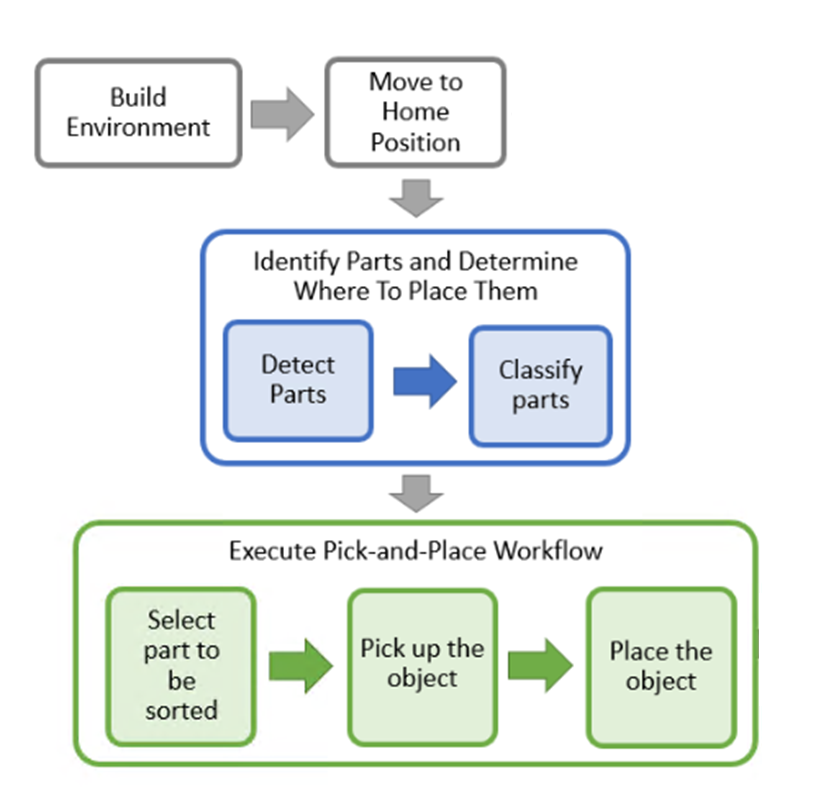

For an implementation that uses Stateflow to schedule the tasks, see [Pick and Place Workflow using Stateflow for MATLAB](docid:robotics_ug#mw_c6d60efe-4e02-4618-88cc-e52a91667f36).

### Scanning the environment to build planning scene for RRT path planner

Before starting the pick-and-place job, the robot goes through a set of tasks to identify the planning scene in the `exampleCommandBuildWorld` function and detects the objects to pick using the `exampleCommandDetectParts` function.

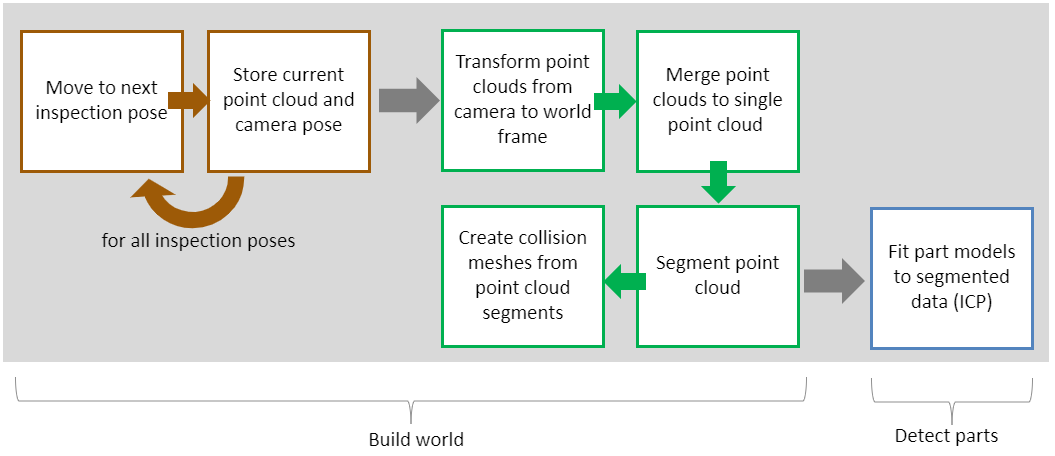

First, the robot moves to predefined scanning poses one by one and captures a set of point clouds of the scene using an onboard depth sensor. At each of the scanning poses, the current camera pose is retrieved by reading the corresponding ROS transformation using [`rostf`](docid:ros_ref#bupf5_j_12) and [`getTransform`](docid:ros_ref#buqbijb). The scanning poses are visualized below:

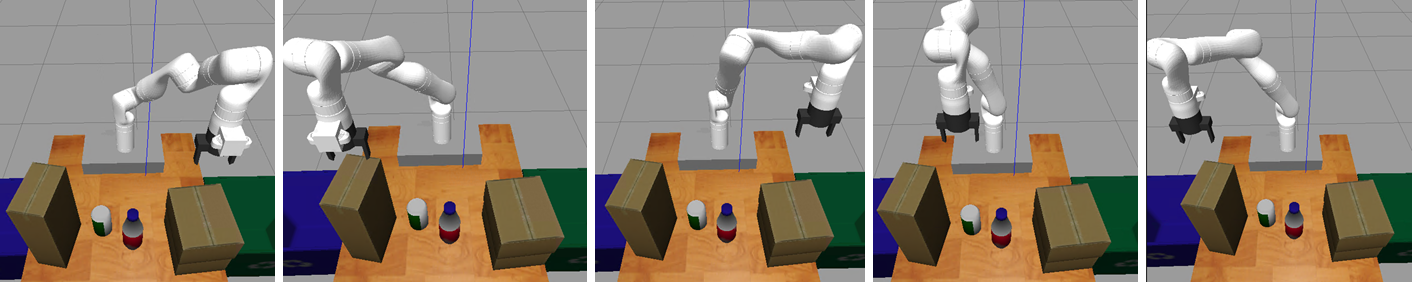

Once the robot has visited all the scanning poses, the captured point clouds are transformed from camera to world frame using [`pctransform`](docid:vision_ref#bupmtw7-1) and merged to a single point cloud using [`pcmerge`](docid:vision_ref#bupmsru-1). The final point cloud is segmented based on Euclidean distance using [`pcsegdist`](docid:vision_ref#mw_c75a2c24-9ee9-4d38-b9e6-f974ffc7bc58). The resulting point cloud segments are then encoded as collision meshes (see [`collisionMesh`](docid:robotics_ref#mw_a620e54b-94a8-41ef-9388-db6daf941221)) to be easily identified as obstacles during RRT path planning. The process from point cloud to collision meshes is shown one mesh at at a time below. 

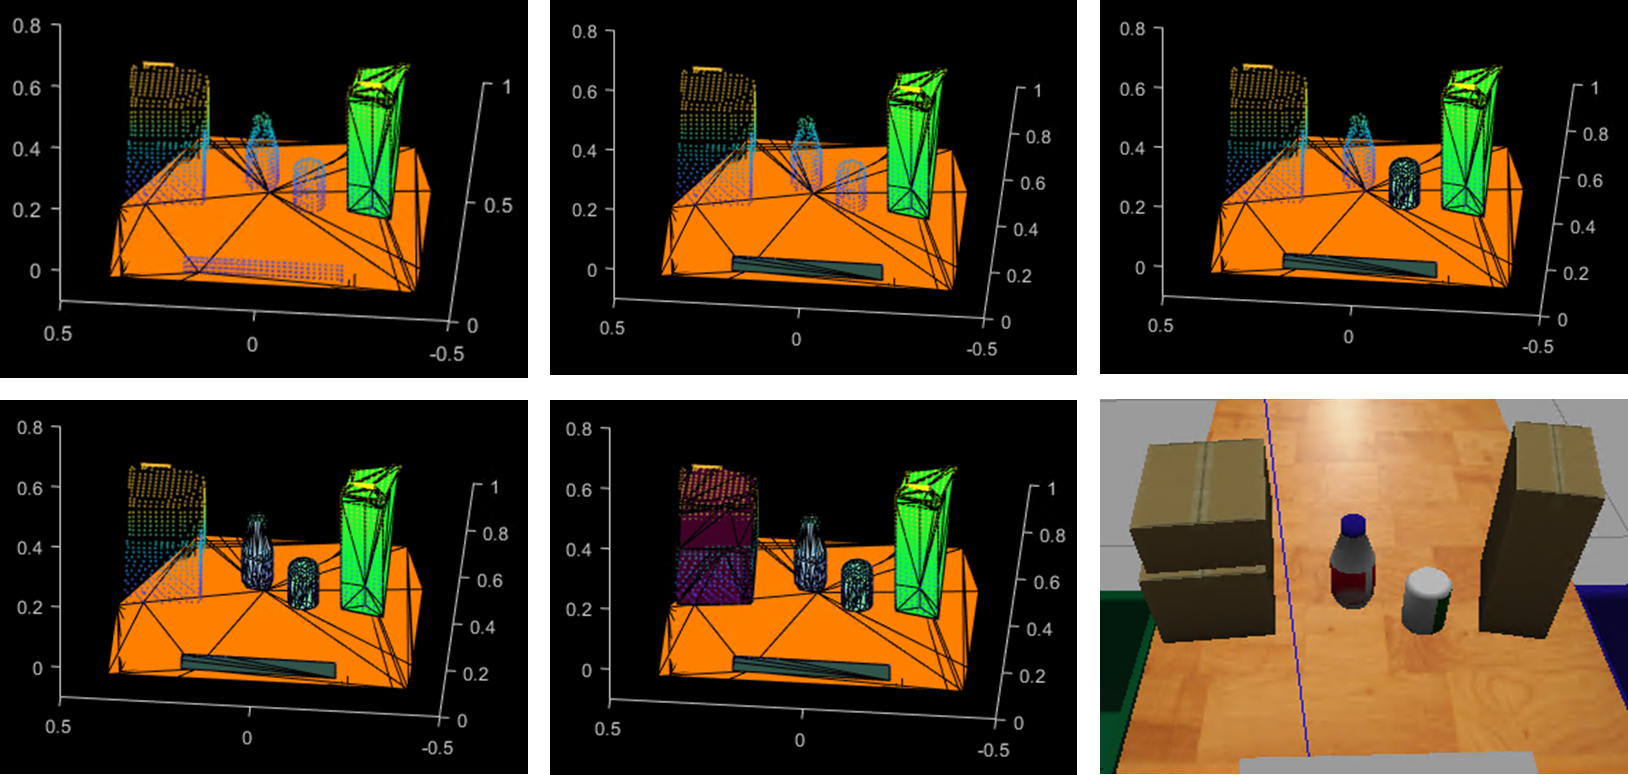

### Opening and closing the gripper

The command for activating the gripper, `exampleCommandActivateGripper`, sends an action request to open and close the gripper implemented in Gazebo. For example, to send a request to open the gripper, the following code is used.

### Moving the manipulator to a specified pose

Most of the task execution consists of instructing the robot to move between different specified poses. The `exampleHelperMoveToTaskConfig` function defines an RRT planner using the [`manipulatorRRT`](docid:robotics_ref#mw_ebddba4d-1dbe-4a60-b626-74349473c4bb) object, which plans paths from an initial to a desired joint configuration by avoiding collisions with specified collision objects in the scene. The resulting path is first shortened and then interpolated at a desired validation distance. To generate a trajectory, the [`trapveltraj`](docid:robotics_ref#mw_c08fb728-410a-4595-86d9-5405020e05a8) function is used to assign time steps to each of the interpolated waypoints following a trapezoidal profile. Finally, the waypoints with their associated times are interpolated to a desired sample rate (every 0.1 seconds). The generated trajectories ensure that the robot moves slowly at the start and the end of the motion when it is approaching or placing an object. 

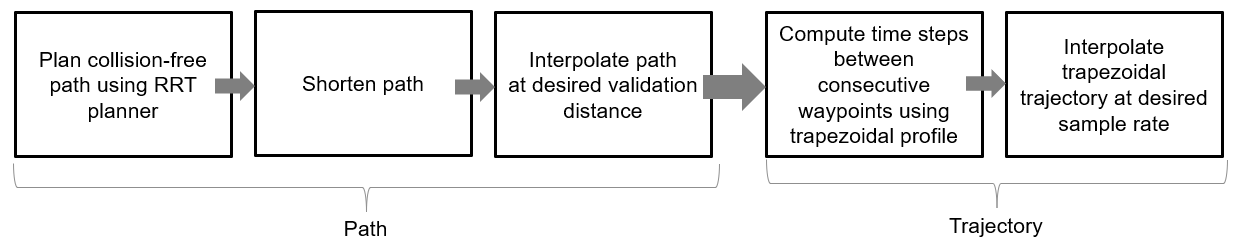

The planned paths are visualized in MATLAB along with the planning scene. 

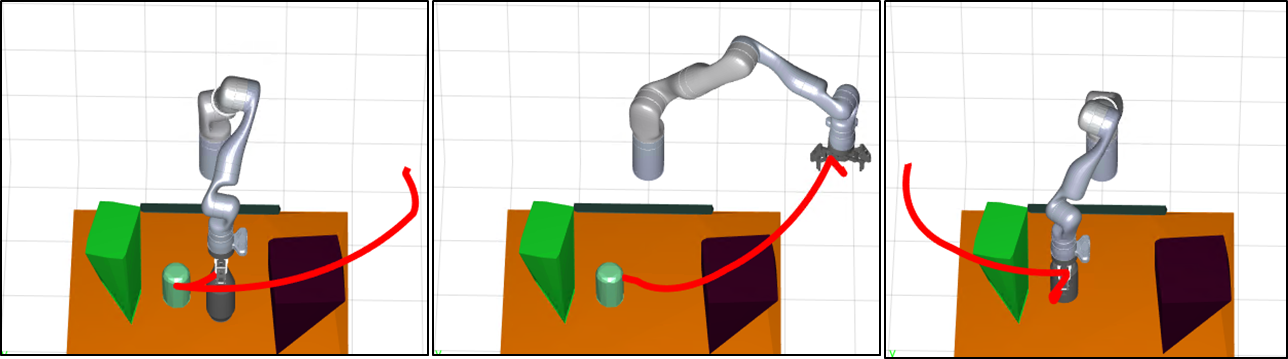

This workflow is examined in detail in the [Pick and Place Workflow Using RRT Planner and Stateflow for MATLAB](docid:robotics_ug#mw_7b5b174d-e478-4f7d-923e-716b4c9c9285) example. For more information about the RRT planner, see [Pick and Place Using RRT for Manipulators](docid:robotics_ug#mw_9b49d589-33c9-4558-8c3d-89142645a775). For simpler trajectories where the paths are known to be obstacle-free, trajectories could be executed using trajectory generation tools and simulated using the manipulator motion models. See [Plan and Execute Task- and Joint-Space Trajectories Using a KINOVA Gen3 Manipulator](docid:robotics_ug.mw_20e8553c-fc75-4688-8696-bac1b2693fa8).

#### Joint Trajectory Controller in ROS

After generating a joint trajectory for the robot to follow, the `example`C`ommandMoveToTaskConfig` function samples the trajectory at the desired sample rate, packages it into joint-trajectory ROS messages and sends an action request to the joint-trajectory controller implemented in the KINOVA ROS package. 

### Detecting and classifying objects in the scene

The functions `exampleCommandDetectParts` and `exampleCommandClassifyParts` use the simulated end-effector depth camera feed from the robot to detect the recyclable parts. Since a complete point cloud of the scene is available from the **Build Environment** step, the iterative closest point (ICP) registration algorithm implemented in [`pcregistericp`](docid:vision_ref#bupmua2-1) identifies which of the segmented point clouds match the geometries of objects that should be picked. 

## Start the Pick-and-Place Workflow

This simulation uses a KINOVA Gen3 manipulator with a gripper attached. 

load('exampleHelperKINOVAGen3GripperGazeboRRTScene.mat'); 
rng(0)

### Initialize the Pick-and-Place Application

Set the initial robot configuration and name of the end-effector body.

initialRobotJConfig =  [3.5797   -0.6562   -1.2507   -0.7008    0.7303   -2.0500   -1.9053];
endEffectorFrame = "gripper";

Initialize the coordinator by giving the robot model, initial configuration, and end-effector name.

coordinator = exampleHelperCoordinatorPickPlaceROSGazeboScene(robot,initialRobotJConfig, endEffectorFrame);

Specify pick-and-place coordinator properties.

coordinator.HomeRobotTaskConfig = getTransform(robot, initialRobotJConfig, endEffectorFrame);
coordinator.PlacingPose{1} = trvec2tform([[0.2 0.55 0.26]])*axang2tform([0 0 1 pi/2])*axang2tform([0 1 0 pi]);
coordinator.PlacingPose{2} = trvec2tform([[0.2 -0.55 0.26]])*axang2tform([0 0 1 pi/2])*axang2tform([0 1 0 pi]);

### Run the Pick-and-Place Application Step by Step

% Task 1: Build world
exampleCommandBuildWorldROSGazeboScene(coordinator);
% Task 2: Move to home position
exampleCommandMoveToTaskConfigROSGazeboScene(coordinator,coordinator.HomeRobotTaskConfig);
% Task 3: Detect objects in the scene to pick
exampleCommandDetectPartsROSGazeboScene(coordinator);

% Task 4: Select next part to pick
remainingParts = exampleCommandPickingLogicROSGazeboScene(coordinator);

while remainingParts==true
    % Task 5: [PICKING] Compute grasp pose
    exampleCommandComputeGraspPoseROSGazeboScene(coordinator);
    
    % Task 6: [PICKING] Move to picking pose
    exampleCommandMoveToTaskConfigROSGazeboScene(coordinator, coordinator.GraspPose);
    
    % Task 7: [PICKING] Activate gripper
    exampleCommandActivateGripperROSGazeboScene(coordinator,'on');
    
    % Part has been picked
    
    % Task 8: [PLACING] Move to placing pose
    exampleCommandMoveToTaskConfigROSGazeboScene(coordinator, ...
    coordinator.PlacingPose{coordinator.DetectedParts{coordinator.NextPart}.placingBelt});
    
    % Task 9: [PLACING] Deactivate gripper
    exampleCommandActivateGripperROSGazeboScene(coordinator,'off');
    
    % Part has been placed
    
    % Select next part to pick
    remainingParts = exampleCommandPickingLogicROSGazeboScene(coordinator);    
end
% Shut down ros when the pick-and-place application is done
rosshutdown;

### Visualize the Pick-and-Place Action in Gazebo

The Gazebo world shows the robot in the working area as it moves parts to the recycling bins. The robot continues working until all parts have been placed.

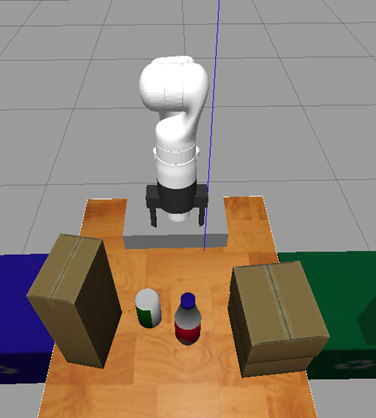

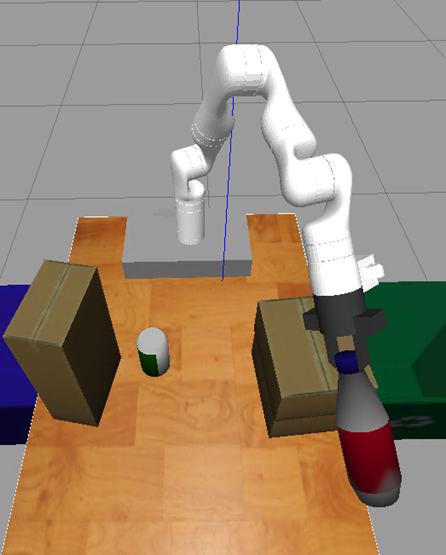

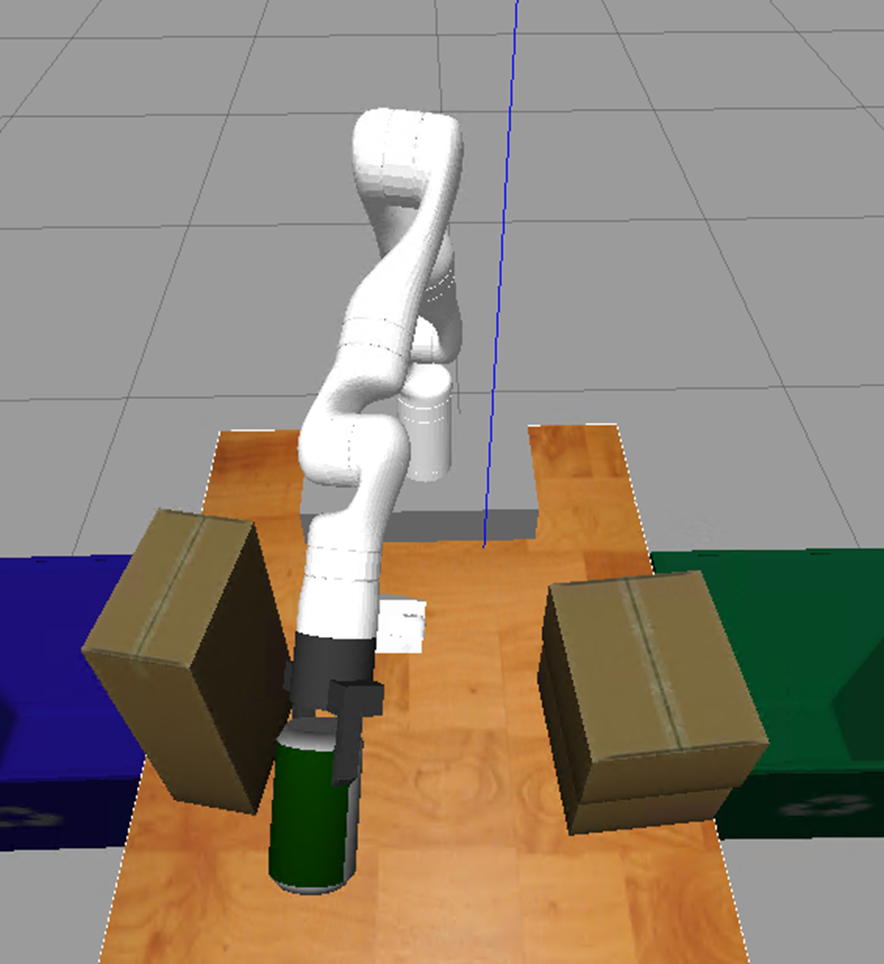

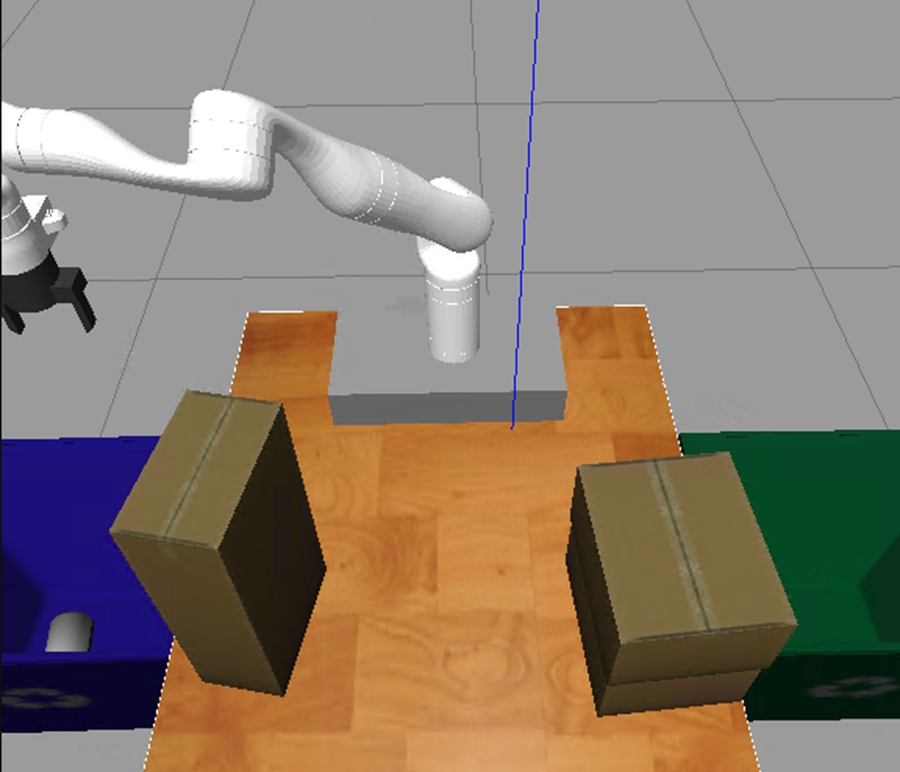

 Copyright 2021 The MathWorks, Inc.